clear; clc; close;

% declaration and initilaization
x_limits = [-10,10];
y_limits = [-10,10];

% set up plotting grid

x_1 = linspace(x_limits(1), x_limits(2))

x_1 =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


x_2 = linspace(y_limits(1), y_limits(2))

x_2 =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010



[x_1_grid, x_2_grid] = meshgrid(x_1, x_2);

% cost function

% evaluate cost function
f = x_1_grid.^2 .* x_2_grid.^2;

% plot cost function
figure;
contourf(x_1_grid, x_2_grid, f, 15, "LineWidth",.001, "DisplayName","Cost, f, (\sim)"); colormap(flipud(summer)); colorbar;
hold on;

% make plot look good
xlim(x_limits); ylim(y_limits);
legend("Location","southwest")
set(gca,"FontSize",12)
set(gca,'BoxStyle','back','Layer','top','XAxisLocation','origin',...
    'YAxisLocation','origin');
set(gca,"LineWidth",2)
xlabel("Design Variable 1, $x_1$, $\left(m\right)$", "Interpreter","latex");
ylabel("Design Variable 2, $x_2$, $\left(m\right)$", "Interpreter","latex");

% contraint functions

% g1 - part 1
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [6+sqrt(6-(x_1-6).^2), y_limits(2) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,0,1], "FaceAlpha",.3, "EdgeColor",[0,0,1], "LineWidth",2, "DisplayName","g_1 infeasible region")

% g1 - part 2
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [6-sqrt(6-(x_1-6).^2), y_limits(1) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,0,1], "FaceAlpha",.3, "EdgeColor",[0,0,1], "LineWidth",2, "DisplayName","g_1 infeasible region")


% g2
boundaryEdges_Xcoords = [5 * ones(size(x_1)), x_limits(2) * ones(size(x_1))];
boundaryEdges_Ycoords = [x_2, fliplr(x_2)];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [1,.25,.75], "FaceAlpha",.3, "EdgeColor",[1,.25,.75], "LineWidth",2, "DisplayName","g_2 infeasible region")

% optimum value

%plot the omptimum
x_1_opt = 5 % optimum design point

x_1_opt = 5

x_2_opt = 6 - sqrt(5) % optimum design point

x_2_opt = 3.7639

%plot(x_1_opt,x_2_opt,"Marker","pentagram","MarkerSize",6,"MarkerEdgeColor",[.5,0,.75],"MarkerFaceColor",[.5,0,.75],"LineStyle","none", "DisplayName","optimum")

[x_opt,f_opt] = fmincon(@(x) x(1).^2 + x(2).^2, [0,0], [],[],[],[],[],[], @(x) constraint(x))


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     4.2679    4.2679


f_opt = 36.4308

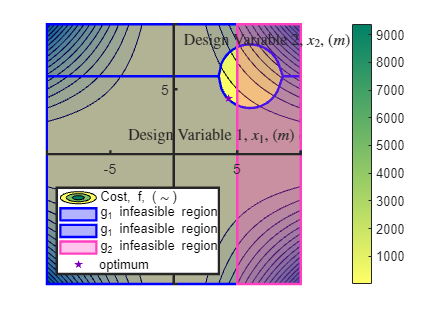

plot(x_opt(1), x_opt(2), "Marker","pentagram","MarkerSize",6,"MarkerEdgeColor",[.5,0,.75],"MarkerFaceColor",[.5,0,.75],"LineStyle","none", "DisplayName","optimum")

function [g, h] = constraint(x)
    g(1) = (x(1)-6).^2 + (x(2)-6).^2 -6;
    g(2) = x(1)-5;

    h = [];
end